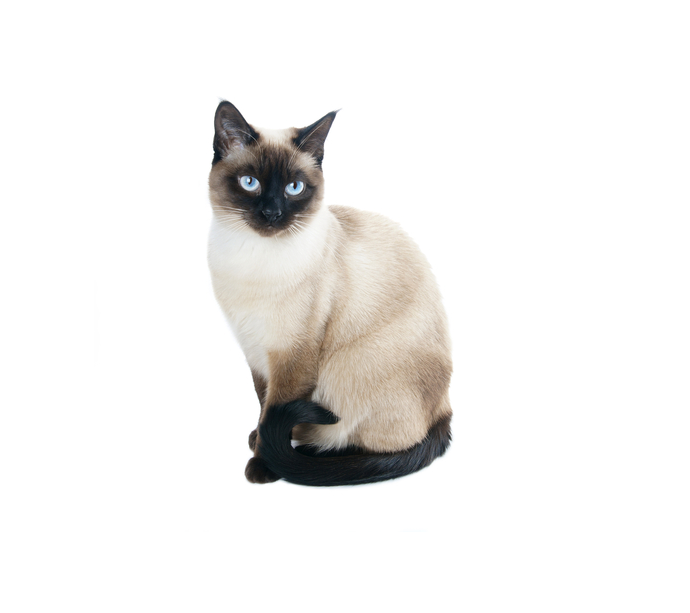

clc;
clear;
close all;

% Read in the image
%img = imread('siamese-cat.png');
img = imread("https://www.arizonapetvet.com/blog/wp-content/uploads/2015/08/shutterstock_134696735.jpg");

% Display the original image
figure(1)
imshow(img);

drawnow()

% Make the image grayscale by just averaging the RGB values

GrayImg = round(sum(img,3)/3);

[U,S,V] = svd(GrayImg);
D = diag(S);
K = rank(S);
D = D(1:K);

Reconstruct the image using the singular values/singular vectors M through N

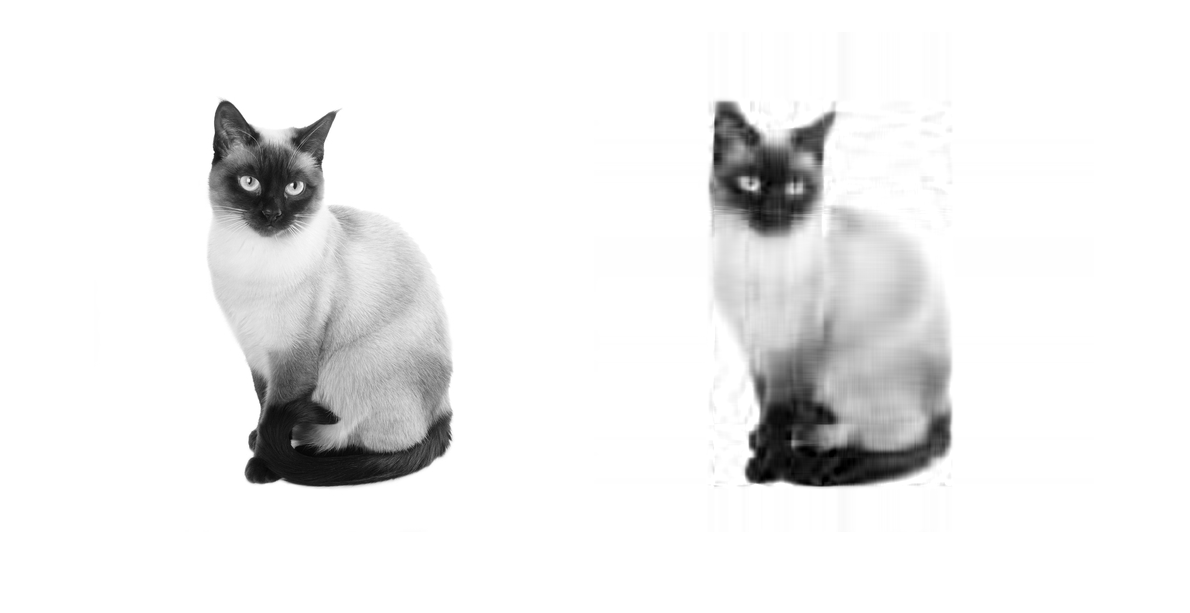

M = 1;
N = 14; % M <= N should hold 

figure();
show = @(M,N) show_(M,N,U,V,S,GrayImg);
Reduced = show(M,N);

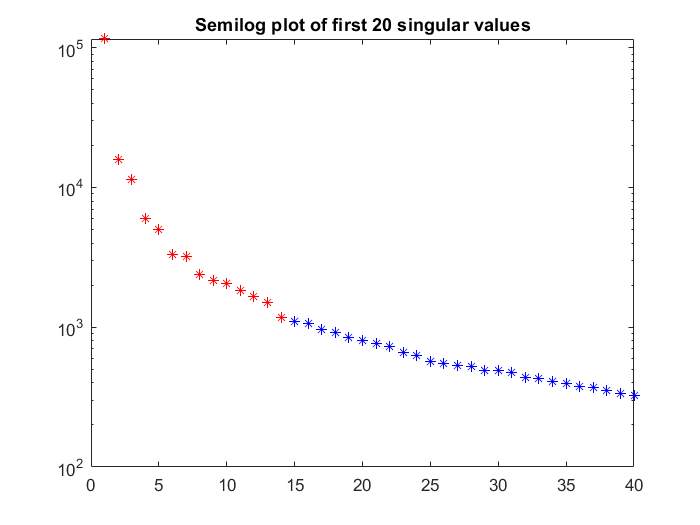


variance_accounted_for = sum(D(M:N).^2)/sum(D.^2);
error = sum(sum((GrayImg - Reduced).^2));

figure();
semilogy(1:40,D(1:40),'b*')
hold on
semilogy(M:N,D(M:N),'r*')
title("Semilog plot of first 20 singular values")


disp(['variance accounted for = ', num2str(round(variance_accounted_for*100,2)),'%'])

variance accounted for = 99.9%


fprintf("L^2 error = %.2f", error)

L^2 error = 13781028.12

Here we define the function that does the work:

function Reduced = show_(M,N, U,V,S,GrayImg) 
    Reduced = U(:,M:N)*S(M:N,M:N)*V(:,M:N)';
    % For imshow you need the correct format for the integers
    figure(2)
    imshow([uint8(GrayImg) uint8(round(Reduced))]);
end